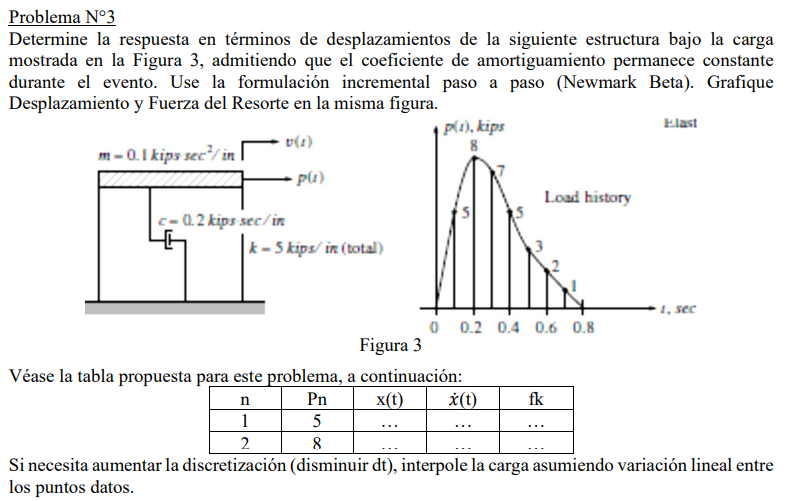

## Respuesta para comparar resultados

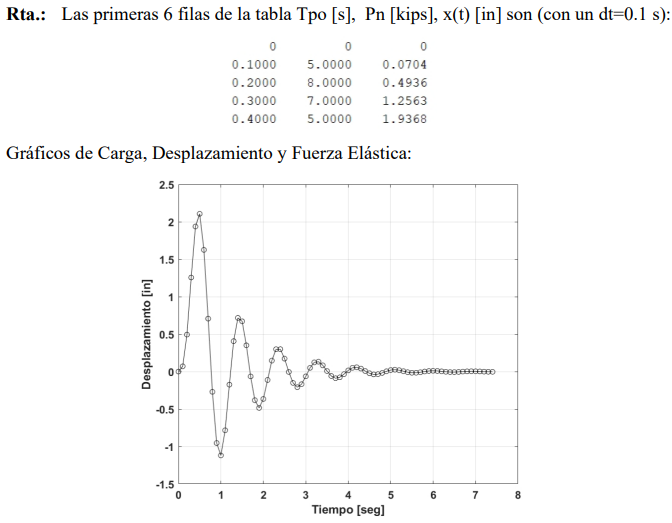

## Resolución por Duhamel para comparar con Newmark Beta

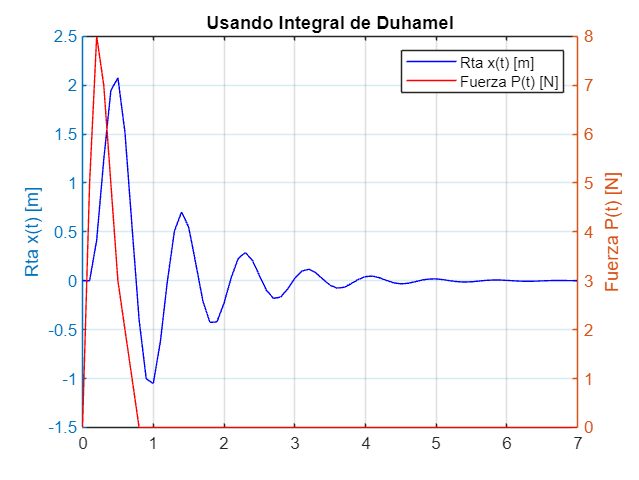

clc; clear;

dt=0.1;
tf=7;
t=0:dt:tf;

e=exp(1);

%% ---------------PARÁMETROS DEL SISTEMA-----------------------
m=0.1;
c=0.2;
k=5;

w=sqrt(k/m);
T=2*pi/w;
zeta=c/(2*m*w);
wd=w*sqrt(1-zeta^2);

%% ------------- DESCRIPCIÓN DE FUERZA EXTERNA ---------------

P=zeros(1,length(t));
P(2)=5; P(3)=8; P(4)=7; P(5)=5; P(6)=3; P(7)=2; P(8)=1; %Valores dato de la fuerza

%% ------------ CALCULO INTEGRAL DE DUHAMEL ------------------

yc = P.*cos(w*t); %Se usa en la integral duhamel
ys = P.*sin(w*t); %Se usa en la integral de duhamel

A = zeros(1,length(t)); %Se usa en la integral de duhamel
B = zeros(1,length(t)); %Se usa en la integral de duhamel

for i=2:length(t)
    A(i) = A(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (yc(i-1)*e^(-zeta*w*dt) + yc(i));
    B(i) = B(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (ys(i-1)*e^(-zeta*w*dt) + ys(i));
end

x_duhamel = A.*sin(w*t) - B.*cos(w*t);

figure
title('Usando Integral de Duhamel')
yyaxis left
plot(t,x_duhamel,'b')
ylabel('Rta x(t) [m]')

yyaxis right
plot(t,P,'r');
ylabel('Fuerza P(t) [N]')
legend('Rta x(t) [m]', 'Fuerza P(t) [N]');
grid on


x_duhamel

x_duhamel =          0         0    0.4156    1.2369    1.9433    2.0766    1.5153    0.5508   -0.3997   -1.0008   -1.0497   -0.6248   -0.0001    0.5113    0.7036    0.5494    0.1798   -0.2025   -0.4257   -0.4200   -0.2292    0.0285    0.2268    0.2888    0.2116    0.0546   -0.0980   -0.1796   -0.1669   -0.0825    0.0231    0.0993    0.1177    0.0807    0.0146   -0.0460   -0.0752   -0.0658   -0.0290    0.0140    0.0430    0.0477    0.0304    0.0028   -0.0211   -0.0313   -0.0258   -0.0098    0.0075    0.0184


## Usando NewMark Beta (Método paso a paso)

Para asegurar la estabilidad, se debe verificar que:

donde h en este caso es dt (el paso en el tiempo).

Se opta por usar la forma explícita que solo usa valores obtenidos en los pasos de tiempo anteriores (en la forma implícita el valor en el paso actual se calcula en función de valores obtenidos en el ***mismo paso*** y en pasos anteriores, por lo que hay que usar métodos iterativos para refinar el valor dentro del mismo paso de tiempo, es más engorroso).

Primero se calculan estos valores:

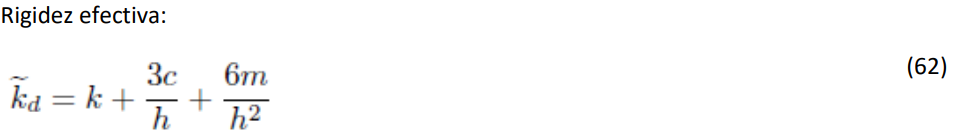

**(cte en el tiempo)**

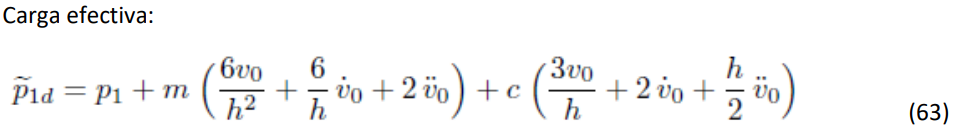

**(se calcula uno por cada paso de tiempo)**

Ya puedo calcular

(de acá despejo v1)

%%---------- CALCULO CON NEWMARK BETA (METODO PASO A PASO) -----------

%para lograr la estabilidad, se debe cumplir que dt/T<=sqrt(3)/pi
disp(['dt/t = ',num2str(dt/T)]);

dt/t = 0.11254


disp(['1/pi = ',num2str(sqrt(3)/pi)]);

1/pi = 0.55133


if dt/T<=sqrt(3)/pi
    disp('Se cumple la condición para asegurar estabilidad por Newmark Beta');
end

Se cumple la condición para asegurar estabilidad por Newmark Beta


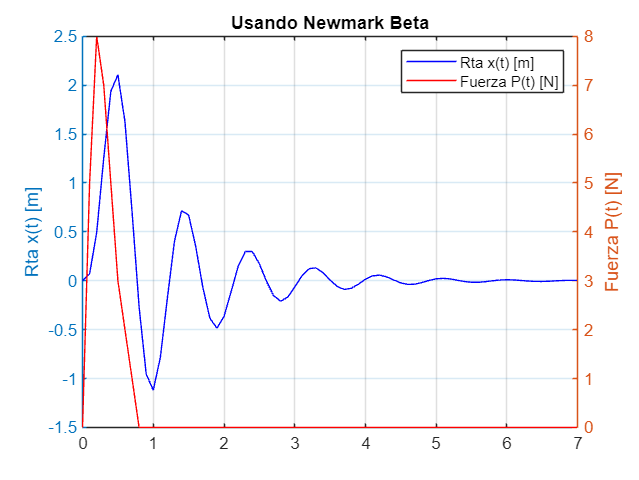


%Inicializo vectores de desplazamiento, velocidad y aceleración
x=zeros(1,length(t));
dx=zeros(1,length(t));
ddx=zeros(1,length(t));

%Establezco condiciones iniciales
x(1)=0;
dx(1)=0;
ddx(1)=0;

%Calculo rigidez efectiva
kd=k+3*c/dt+6*m/(dt^2);

%Inicializo vector de carga efectiva
pd=zeros(1,length(t));

%Aplico ecuaciones de Newmark Beta
for i=2:length(t) %ojo, calculo del instante 2 en adelante
    pd(i)=P(i)+m*(6*x(i-1)/(dt^2) + 6/dt*dx(i-1)+2*ddx(i-1))+c*(3*x(i-1)/dt+2*dx(i-1)+dt*ddx(i-1)/2);
    x(i)=pd(i)/kd;
    dx(i)=-2*dx(i-1)-dt*ddx(i-1)/2+3*(x(i)-x(i-1))/dt;
    ddx(i)=6*(x(i)-x(i-1))/(dt^2)-6*dx(i-1)/dt-2*ddx(i-1);
end


figure
yyaxis left
plot(t,x,'b')
ylabel('Rta x(t) [m]')
hold on

yyaxis right
plot(t,P,'r');
ylabel('Fuerza P(t) [N]')
legend('Rta x(t) [m]', 'Fuerza P(t) [N]');
title('Usando Newmark Beta')
grid on

hold off


x

x =          0    0.0704    0.4936    1.2563    1.9368    2.1065    1.6250    0.7073   -0.2697   -0.9535   -1.1188   -0.7835   -0.1738    0.4063    0.7167    0.6718    0.3506   -0.0644   -0.3821   -0.4846   -0.3650   -0.1114    0.1464    0.2988    0.2992    0.1731   -0.0048   -0.1506   -0.2081   -0.1680   -0.0636    0.0500    0.1233    0.1321    0.0836    0.0080   -0.0582   -0.0886   -0.0765   -0.0340    0.0156    0.0502    0.0578    0.0397    0.0078   -0.0219   -0.0374   -0.0345   -0.0174    0.0041


## Comparación entre Duhamel y Newmark Beta

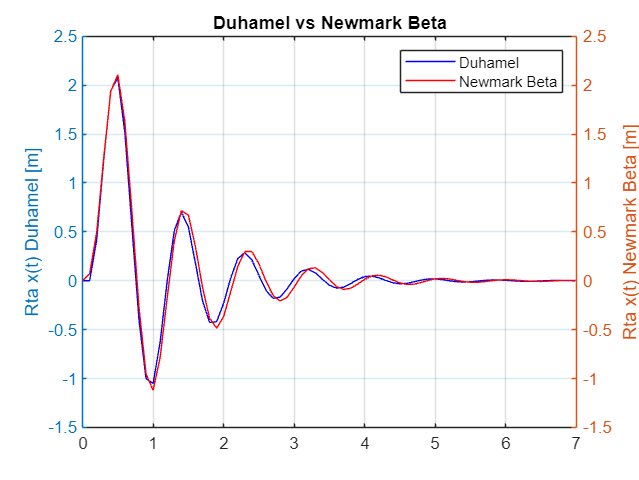

figure
yyaxis left
plot(t,x_duhamel,'b')
ylabel('Rta x(t) Duhamel [m]')
hold on

yyaxis right
plot(t,x,'r');
ylabel('Rta x(t) Newmark Beta [m]')
legend('Duhamel', 'Newmark Beta');
title('Duhamel vs Newmark Beta')
grid on

hold off